tracks_matrix = h5read('Quadrant.analysis.h5','/tracks');
disp(size(tracks_matrix))

       38757           5           2           2



% frames x nodes x 2 (x,y) x tracks
% nose earR earL tailbase body
% fill NAs
tracks_matrix = fillmissing(tracks_matrix, 'movmean', 7);
% read timestamp
tstamp = csvread('timeStamps.csv', 1);
tstamp = tstamp(251:end,2);
% bin Data
tracks_bined = BinData(tracks_matrix, 6, 'mean');
time_bined = BinData(tstamp, 6, 'mean');
% find approximate head position by finding mid point between nose and body
head_coord = 1/2*(tracks_bined(:,1,:,:) + tracks_bined(:,5,:,:));

% quadrant center
qcenter = [249,295]; %[xcenter, ycenter]
qcode = [head_coord(:,:,1,1)<=qcenter(1), head_coord(:,:,2,1) > qcenter(2), head_coord(:,:,1,2)<=qcenter(1),...
    head_coord(:,:,2,2)>qcenter(2)];
qseries = [qcode(:,1)+qcode(:,2)*2,qcode(:,3)+qcode(:,4)*2];
qseries(qseries==1) = 4; qseries(qseries == 0) = 1;

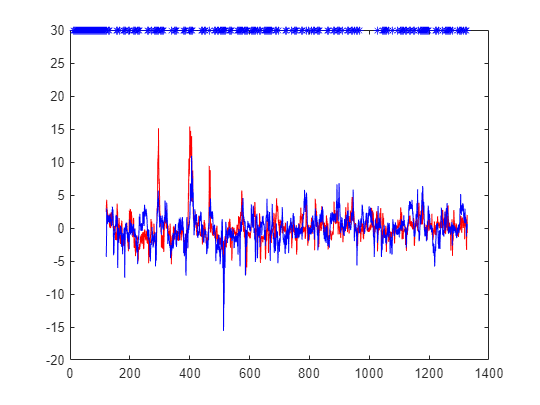

% load neural data
m1_neural = XZ98.MS{2}.FiltTraces(1801:end,XZ98.MS{2}.goodCellVec); % remove first 2 min
m2_neural = XZ91.MS{2}.FiltTraces(1801:end,XZ91.MS{1}.goodCellVec);
m1_tstamp = XZ98.TimeStamp.Ts{2}.Ms(1801:end);
m2_tstamp = XZ91.TimeStamp.Ts{2}.Ms(1801:end);
% get PLS
[PLS1, PLS2, USV] = GetPLSC(m1_neural, m2_neural);
figure, plot(m1_tstamp/1000,-PLS1(:,3),'r'), hold on, plot(m2_tstamp/1000,-PLS2(:,3),'b')
% find same quadrant time point
same_q_t = find(qseries(:,1) == qseries(:,2));
plot(time_bined(same_q_t)/1000, ones(1,length(same_q_t))*30,'b*');